# Numerical Methods Assignment 3

Group 11

Noah Labuschagne S6621635

Danail Valov S5609895

Bashar Alsayed S4029291

**Instructions:**

- Submit the assignment by the deadline on Monday October 19 at 14:00 via Brightspace. All group members must be enrolled in the group before the assignment is submitted.

- **Submit two files: this .mlx file and an .pdf export of the same file. Save both files as NM_AS3_GroupX.mlx and NM_AS3_GroupX.pdf, replacing the X by your group number.**

- Ensure your group number, names and student numbers are at the top of the document.

- **Consult the course description for details** on the assignment, including information on the discussion and the generative AI policy.

- Include a statement on the ways in which you used generative AI, if any, in the box below. If you worked individually, ensure every group members writes their own statement.

- This type of MATLAB file is called a Live Code File Format (.mlx). It allows you to have all code in one place, and show code, generated figures, text, and equations all next to eachother. It is fairly self-explanatory, but this page and links within it provide some further explanation: [http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.](http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.) You are welcome to remove the text of the assignment or keep it and add in your solutions. 

## Generative AI statement

#### *Noah Labuschagne *

AI was not used to generate any code. AI was used infrequently for debugging.

#### *Danail Valov *

AI was not used to generate code; it was used to find sources to specific syntax questions I had regarding the software and to check for bugs and typos once the code was already written out.

#### *Bashar Alsayed *

## Set-up Problem 1 (12 pts.)

The main functions you will use in Problem 1 are the following. Define the functions here, paying attention to efficient implementation. Ensure you call these functions when solving problem 1. You may not use built-in ODE solvers throughout problem 1.

% Implementation of explicit Euler
function [t, x] = explicit_euler(f, x0, t0, h, tf)
it = 1;
t = t0:h:tf;
x = zeros(length(x0), length(t));

x(:, it) = x0;

for n = 1:(length(t)-1)
    x1 = x(:, it) + h * f(t(it), x(:, it));
    it = it + 1;
    x(:, it) = x1;
end
end

% Implementation of Improved Euler
function [t, x] = improved_euler(f, x0, t0, h, tf)
it = 1;
t = t0:h:tf;
x = zeros(length(x0), length(t));

x(:, it) = x0;

for n = 1:(length(t)-1)
    predictor = x(:, it) + h * f(t(it), x(:, it));
    x1 = x(:, it) + h/2*(f(t(it), x(:, it)) + f(t(it+1), predictor));
    it = it + 1;
    x(:, it) = x1;
end
end

% Implementation of RK4
function [t, x] = RK4(f, x0, t0, h, tf)
it = 1;
t = t0:h:tf;
x = zeros(length(x0), length(t));

x(:, it) = x0;

for n = 1:(length(t)-1)

    k1 = f(t(it),           x(:, it));
    k2 = f(t(it) + h/2,     x(:, it) + (h/2)*k1);
    k3 = f(t(it) + h/2,     x(:, it) + (h/2)*k2);
    k4 = f(t(it) + h,       x(:, it) + h*k3);
    
    x1 = x(:, it) + (h/6) * (k1 + 2*k2 + 2*k3 + k4);

    it = it + 1;
    x(:, it) = x1;
end
end

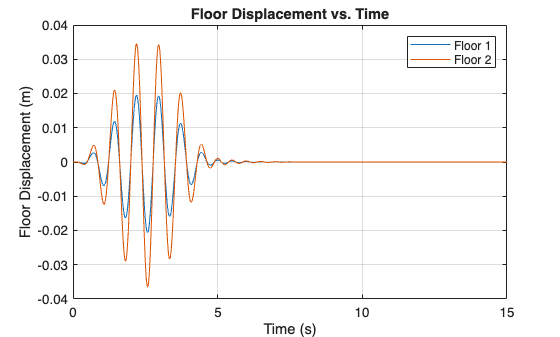

% Implementation of implicit Euler
function [t, x] = implicit_euler(f, x0, t0, h, tf)
it = 1;
t = t0:h:tf;
x = zeros(length(x0), length(t));


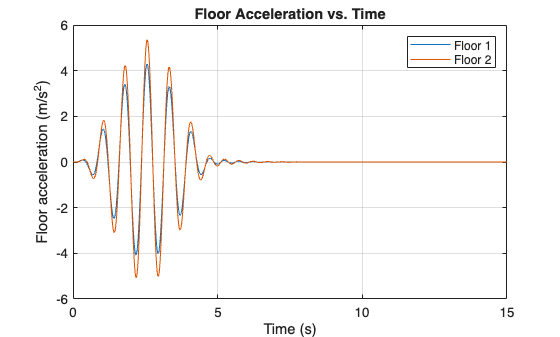

x(:, it) = x0;

% The governing equations are linear: f(t,x) = A*x + b(t).
% Extract A and b(t) from f so that the same f used by the explicit methods is used.

b0 = f(t0, zeros(length(x0), 1));
A = zeros(length(x0));

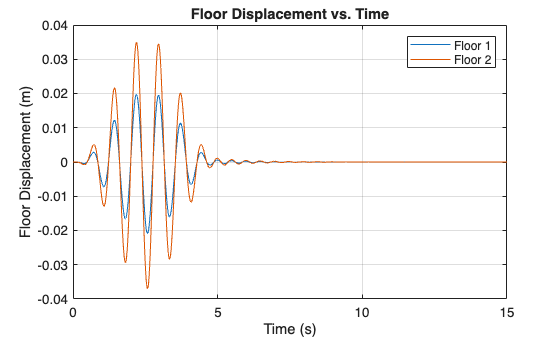

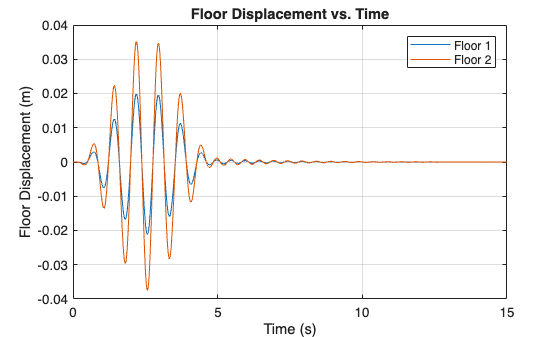

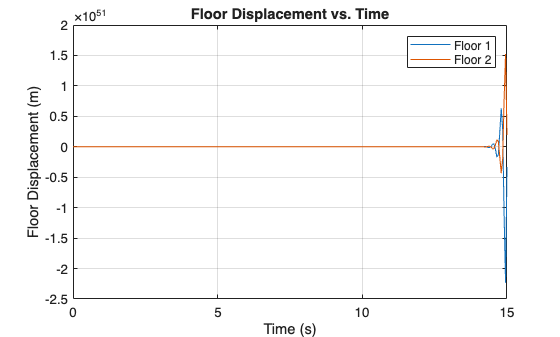

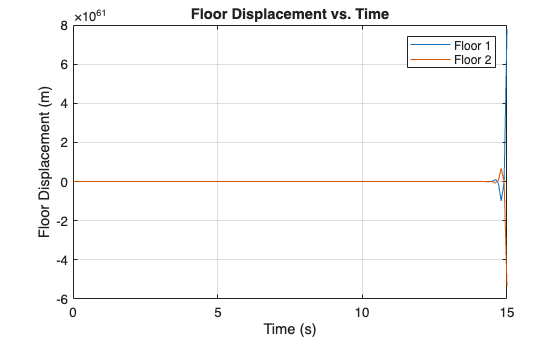

for j = 1:length(x0)
    e = zeros(length(x0), 1);
    e(j) = 1;
    A(:, j) = f(t0, e) - b0;
end

% The matrix (I - h*A) is constant, so LU factorization is performed ONCE
% outside the time-stepping loop. This pays the O(n^3) cost a single time and
% lets every subsequent step use cheap O(n^2) forward/back substitutions.
[L, U, P] = lu(eye(length(x0)) - h*A);

for n = 1:(length(t)-1)
    % Forcing evaluated at the future time t(n+1): b(t(n+1)) = f(t(n+1), 0)
    b = f(t(it+1), zeros(length(x0), 1));

    % Solve (I - h*A) x(n+1) = x(n) + h*b(t(n+1)) using the precomputed LU factors
    x1 = U \ (L \ (P * (x(:, it) + h * b)));

    it = it + 1;
    x(:, it) = x1;
end
end

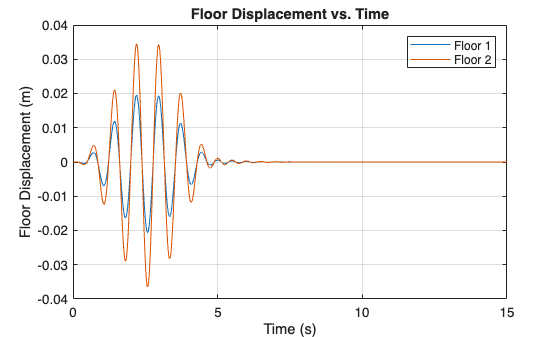

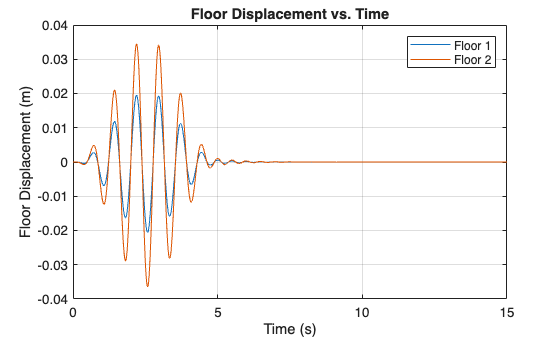

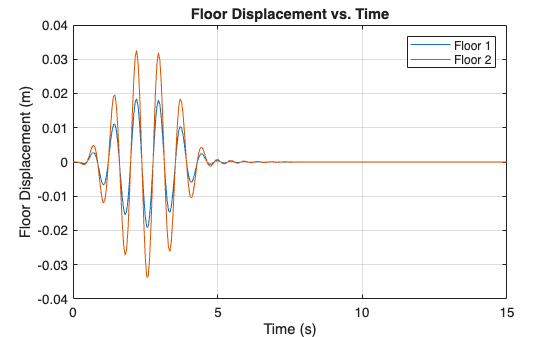

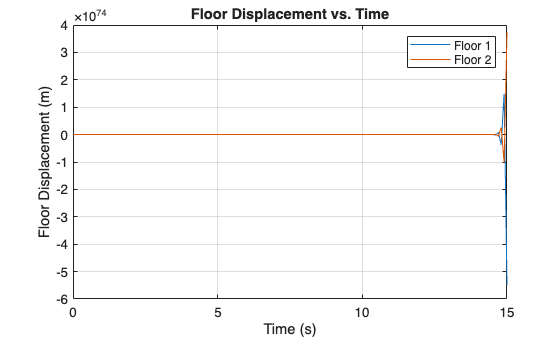

% Implementation of the bisection method
function [root, rootvec] = bisection_method(f, l, u, maxit, tol)
m = ( l + u ) / 2;
it = 1;
rootvec = zeros(1, maxit);

while it <= maxit && abs((m-l)/m) > tol
rootvec(it) = m;
prod = f(l) * f(m);
if prod < 0
u = m ;
else
l = m ;
end
m = ( l + u ) / 2; 
it = it + 1; 
end
root = m;
rootvec = rootvec(rootvec ~= 0);
end

## Problem 1: Seismic Response of a Two-Story Building (50 pts)

A two-story building is subjected to horizontal ground motion during an earthquake. The building is modeled as a two-degree-of-freedom mass-spring-damper system.

Each floor is assumed to behave as a rigid mass, while the lateral stiffness and energy dissipation provided by the columns are represented by linear springs and viscous dampers.

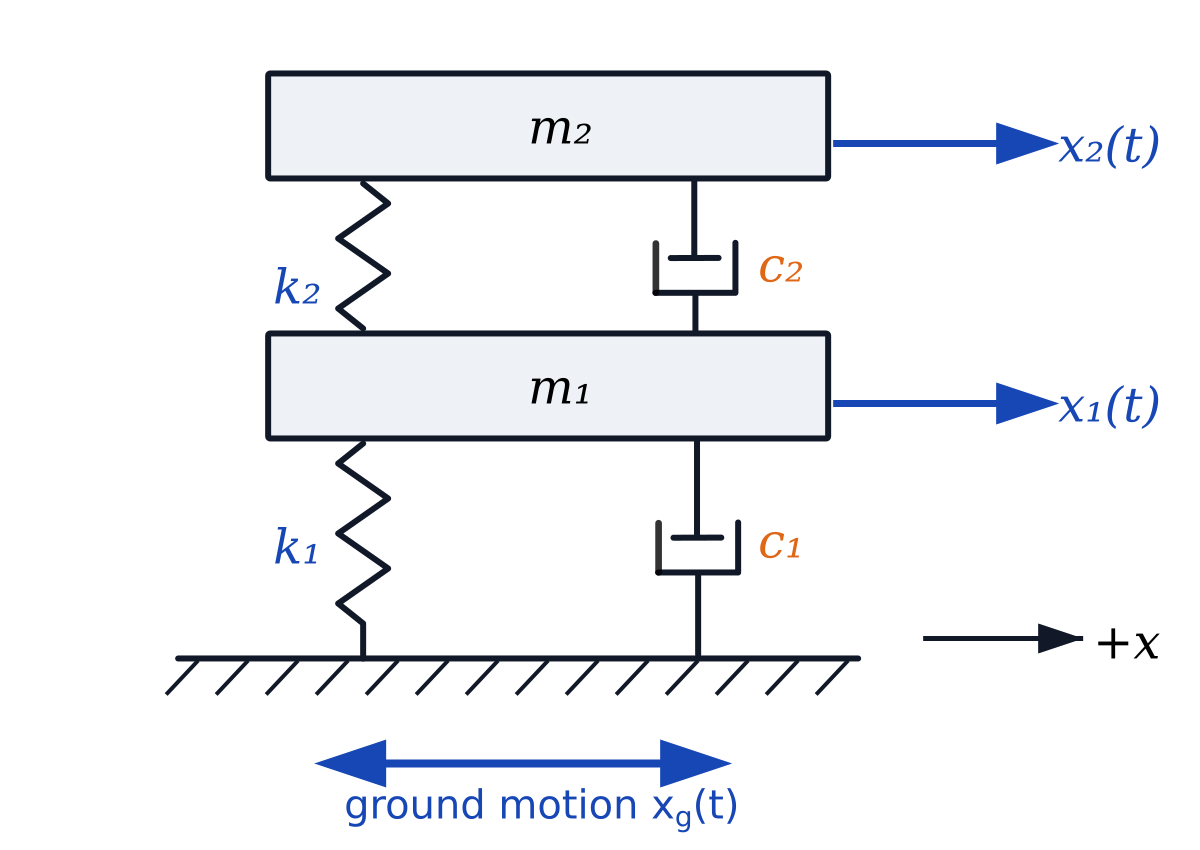

Let:

- $x_1(t)$ be the horizontal displacement of the first floor relative to the ground

- $x_2(t)$ be the horizontal displacement of the second floor relative to the ground

- $m_1$ and $m_2$ be the masses of the first and second floors

- $k_1$ and $k_2$ be the lateral stiffnesses of the first and second stories

- $c_1$ and $c_2$ be the corresponding viscous damping coefficients

- $x_g(t)$ be the horizontal ground displacement

- $a_g(t)=\frac{d^2{x}_g(t)}{dt^2}$ be the ground acceleration

The equations of motion are


$$
 m_1\frac{d^2x_1}{dt^2}
 +(c_1+c_2)\frac{dx_1}{dt}-c_2\frac{dx_2}{dt}
 +(k_1+k_2)x_1-k_2x_2
 =
 -m_1a_g(t),
$$



$$
 m_2\frac{d^2x_2}{dt^2}
 -c_2\frac{dx_1}{dt}+c_2\frac{dx_2}{dt}
 -k_2x_1+k_2x_2
 =
 -m_2a_g(t).\\
$$


### Building parameters

Use the following parameters for the reference building:

### Ground acceleration

The earthquake is represented by the following simplified ground-acceleration function:


$$
 a_g(t)=
 \begin{cases}
 0.30\cdot g\sin(8t)
 \sin^2\left(\frac{\pi t}{5}\right),
 &0\leq t\leq5,\\[8pt]
 0,
 &t>5,
 \end{cases}
$$


where


$$
 g=9.81\ \mathrm{m/s^2}.
$$


The factor


$$
 \sin^2\left(\frac{\pi t}{5}\right)
$$


acts as an envelope that allows the ground excitation to begin and end smoothly.

Simulate the building response over the time interval


$$
 0\leq t\leq15\ \mathrm{s}.
$$


This interval includes both the forced response during the earthquake and the free vibration of the building after the ground excitation has stopped.

### Initial conditions

The building is initially at rest. Therefore,


$$
 x_1(0)=0,\qquad x_2(0)=0,
$$


and


$$
 \frac{dx_1}{dt}(0)=0,\qquad \frac{dx_2}{dt}(0)=0.
$$


### Response quantities

The first-story and second-story interstory drifts are defined as


$$
 \delta_1(t)=x_1(t),
 \qquad
 \delta_2(t)=x_2(t)-x_1(t).
$$


Because $x_1(t)$ and $x_2(t)$ are displacements relative to the ground, the absolute floor accelerations are


$$
 a_{1,\mathrm{abs}}(t)=\frac{d^2x_1(t)}{dt^2}+a_g(t),
$$



$$
 a_{2,\mathrm{abs}}(t)=\frac{d^2x_2(t)}{dt^2}+a_g(t).
$$


We are interested in the maximum value of these quantities in absolute value.

### Structural performance requirements

The reference building satisfies the structural performance requirements only if all three criteria below are met over the complete simulation interval.

The drift requirements are related to structural deformation and potential damage. The acceleration requirement is related to occupant comfort and the protection of equipment inside the building.

### Problem 1a. Transform to system of first-order ODEs (5 pts)

i. Formulate the governing equations as a system of first-order ordinary differential equations. Include the initial conditions. You may include a hand-written derivation with a picture, but make sure it is legible. No code is needed for this part i.

ii. Define the governing equations in code.

# Solution 1a

#### Solution 1a i)

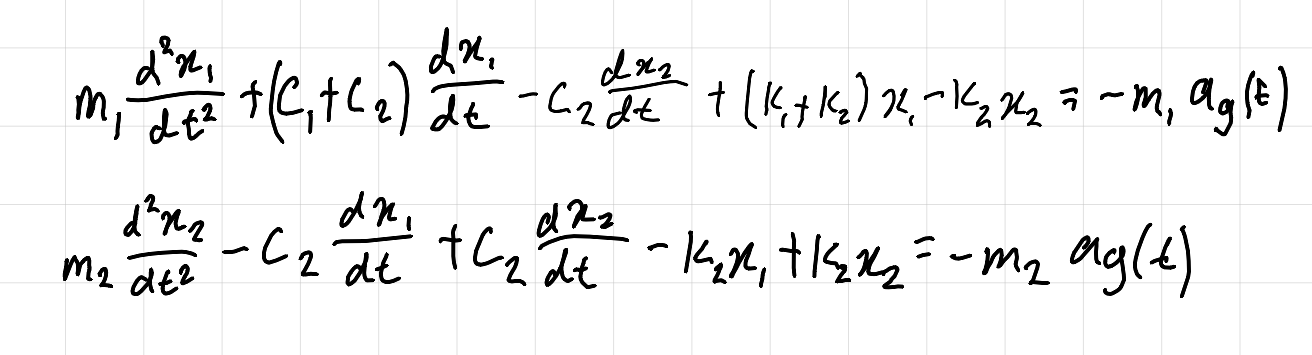

The equations of motion were taken fromthe beginning of Problem 1 and alterations were made to the notation in order to linearize these second order differential equations.Namely, dx1/dt was converted to y1, dx2/dt was converted to y2, and their corresponding derivatives  were converted to dy1/dt and dy2/dt respectively.

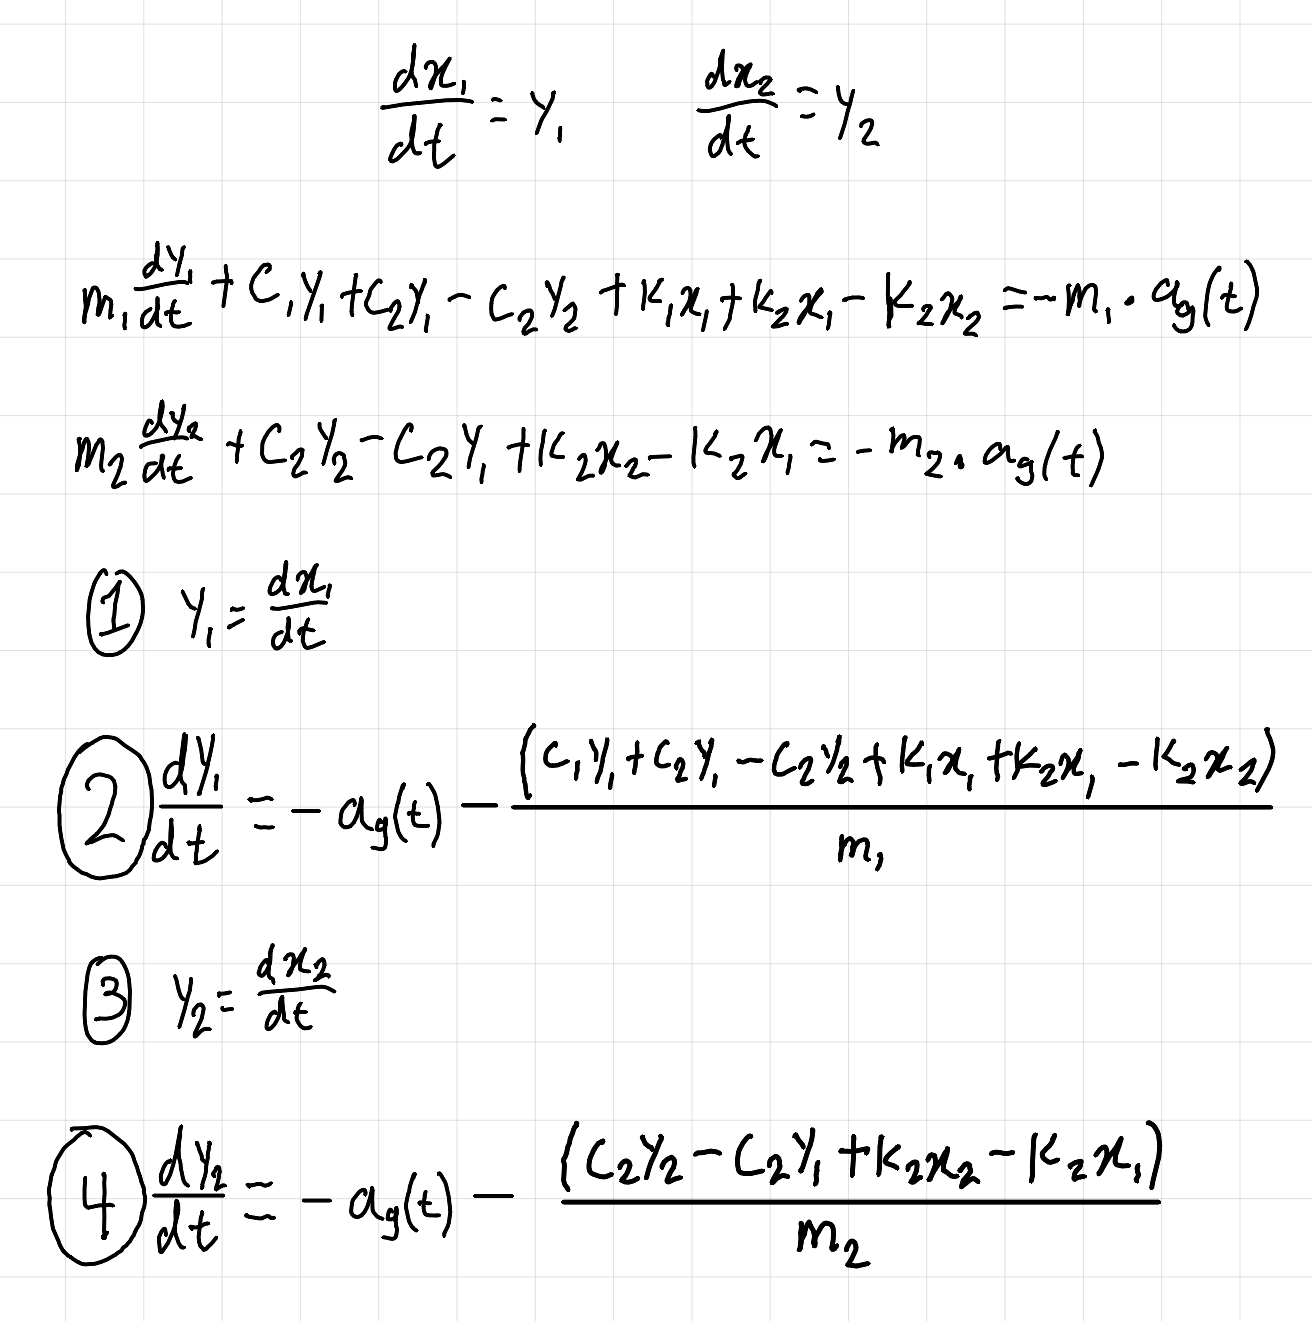

This led to the results presented in the figure above where equation 1 and equation 3 are simply y1 = dx1/dt and y2 = dx2/dt, while equations 2 and 4 are simply the values of dy1/dt and dy2/dt when isolated with respect to the equations of motion. These equations are also contained in the dy matrix in solution 1a. ii).

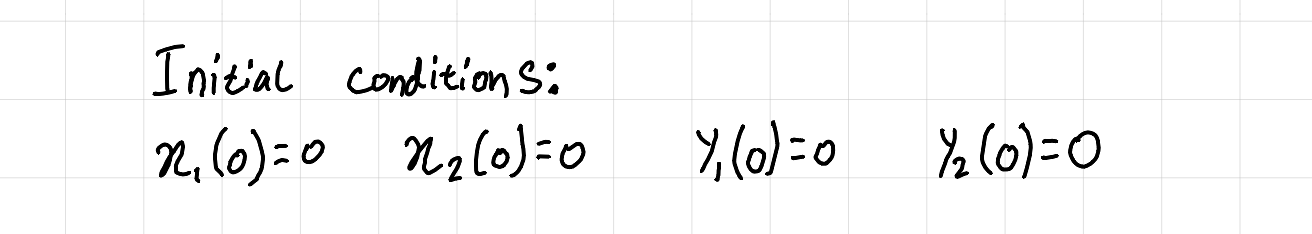

The Initial conditions are identical to the initial conditions which are provided in the instructions for problem 1.

#### Solution 1a ii)

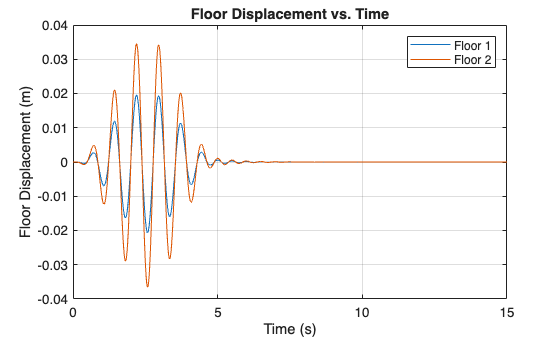

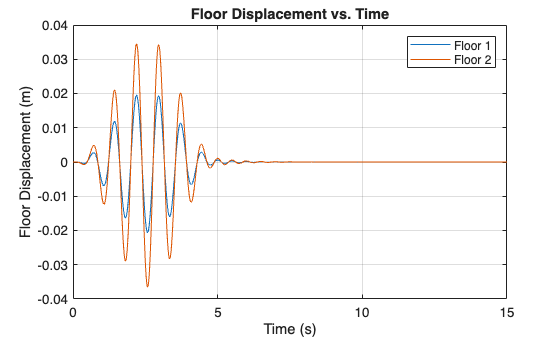

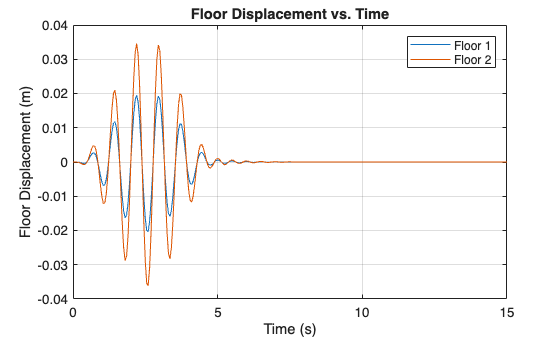

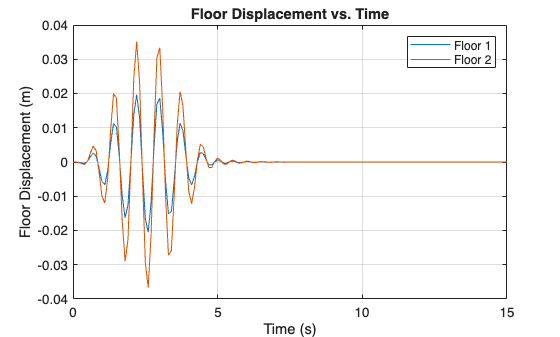

% Initial Conditions

initial_conditions = [0; 0; 0; 0];


% Function governing ground acceleration

function a = ag(t) 
    g = 9.81;
    if t <= 5
        a = 0.30 * g * sin(8*t) * sin(pi*t/5)^2;
    else
        a = 0;
    end
end


% Function dy which contains the 4 governing equations

function dy = g(t, y)
    m1 = 20000;
    m2 = 15000;
    k1 = 8000000;
    k2 = 5000000;
    c1 = 120000;
    c2 = 80000;


    dy = [y(2);
          -ag(t) - (c1*y(2) + c2*y(2) - c2*y(4) + k1*y(1) + k2*y(1) - k2*y(3))/m1;
          y(4);
          -ag(t) - (c2*y(4) - c2*y(2) + k2*y(3) - k2*y(1))/m2];
end

### Problem 1b. Numerically simulate the seismic response (5 pts)

Numerically simulate the solution to the system using RK4 with step-size $h_{\text{ref}} = 10^{-4}$ over a time-inverval ranging from $t=0$ to $t=15s$. Plot the floor displacement for both floors. This solution will serve as the reference solution for the rest of the problem. 

# Solution 1b

h  = 0.0001;
t0 = 0;

refference_RK4_leading_order_error_term = 1.0000e-16

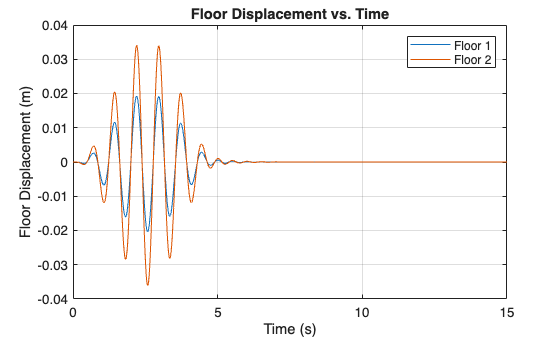

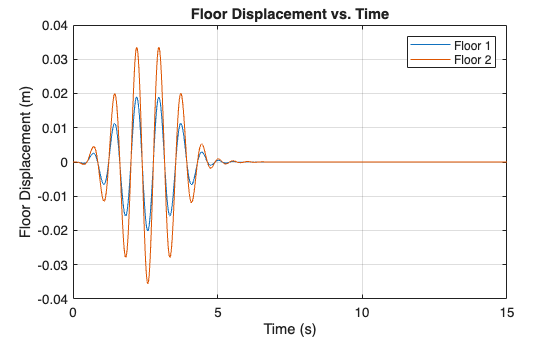

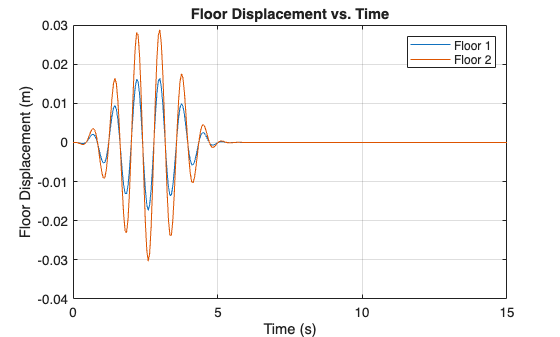

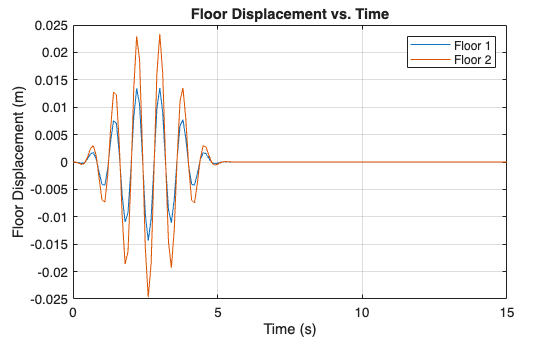

tf = 15;

[t, y] = RK4(@g, initial_conditions, t0, h, tf);

max_delta1 = 0;
max_delta2 = 0;
max_a1abs = 0;
max_a2abs = 0;

floor_displacement = zeros(2, length(t));
floor_acceleration = zeros(2, length(t));

for n = 1:length(t)

 % Floor Displacement
 delta1 = y(1, n);
 delta2 = y(3, n) - y(1, n);

 % Absolute Floor Acceleration
 dy = g(t(n), y(:, n));
 a1abs = dy(2) + ag(t(n));
 a2abs = dy(4) + ag(t(n));

 
 % List of Floor Displacement's and Floor Acceleration
 floor_displacement(1, n) = delta1;
 floor_displacement(2, n) = delta2;
 floor_acceleration(1, n) = a1abs;
 floor_acceleration(2, n) = a2abs;

end

figure
plot(t, y(1,:), t, y(3,:))
xlabel('Time (s)')
ylabel('Floor Displacement (m)')
legend('Floor 1', 'Floor 2')

title('Floor Displacement vs. Time')
grid on
figure
plot(t, floor_acceleration(1,:), t, floor_acceleration(2,:))
xlabel('Time (s)')
ylabel('Floor acceleration (m/s^2)')
legend('Floor 1', 'Floor 2')
title('Floor Acceleration vs. Time')
grid on

Through the use of RK4, the floor displacement of both floors was approximated with a step sizes of h = 0.0001 from t = 0s to t = 15s. These displacements were then plotted on a displacement-time graph.

### Problem 1c. Compare different explicit methods (15 pts)

Numerically simulate the solution to the system using the explicit numerical methods introduced in the lectures (explicit Euler, improved Euler, and RK4) over a time period ranging from $t=0$ to $t=15s$ with different time-steps ( $h=0.005, 0.01, 0.05, 0.1$). Compare the floor displacements obtained with the different methods and discuss their accuracy and suitability for this problem, by comparing the computed solutions against the reference solution.

# Solution 1c

h  = [0.005, 0.01, 0.05, 0.1];

0.019503 m


0.015039 m


for i = 1:length(h)

4.2957 m/s^2


5.3528m/s^2


    [t, y] = explicit_euler(@g, initial_conditions, t0, h(i), tf);

    max_delta1 = 0;
    max_delta2 = 0;
    max_a1abs = 0;
    max_a2abs = 0;

    for n = 1:length(t)

     % Floor Displacement
    delta1 = y(1, n);
    delta2 = y(3, n) - y(1, n);
    end

figure
plot(t, y(1,:), t, y(3,:))
xlabel('Time (s)')
ylabel('Floor Displacement (m)')
legend('Floor 1', 'Floor 2')
title('Floor Displacement vs. Time')
grid on
end

for i = 1:length(h)

    [t, y] = improved_euler(@g, initial_conditions, t0, h(i), tf);

    max_delta1 = 0;
    max_delta2 = 0;
    max_a1abs = 0;
    max_a2abs = 0;

    for n = 1:length(t)

     % Floor Displacement
    delta1 = y(1, n);
    delta2 = y(3, n) - y(1, n);
    end

figure
plot(t, y(1,:), t, y(3,:))
xlabel('Time (s)')
ylabel('Floor Displacement (m)')
legend('Floor 1', 'Floor 2')
title('Floor Displacement vs. Time')
grid on
end


for i = 1:length(h)

    [t, y] = RK4(@g, initial_conditions, t0, h(i), tf);

    max_delta1 = 0;
    max_delta2 = 0;
    max_a1abs = 0;
    max_a2abs = 0;

    for n = 1:length(t)

     % Floor Displacement
    delta1 = y(1, n);
    delta2 = y(3, n) - y(1, n); 
    end

figure
plot(t, y(1,:), t, y(3,:))
xlabel('Time (s)')
ylabel('Floor Displacement (m)')
legend('Floor 1', 'Floor 2')
title('Floor Displacement vs. Time')
grid on 
end

Since there is a very large number of data points, plots of the displacements of both floors are used to assess and compare the three numerical methods at the reference step size to the reference solution in 1b). 

For the explicit euler method, the computed solutions for h = 0.005 and h = 0.01 are both stable and approximate the behaviour of the reference solution, while the computed solutions for h = 0.05 and h = 0.1 are unstable and continue growing into late times with displacement values reaching as high as 10^51 and 10^61 respectively.

For the improved euler method, the computed solutions for h = 0.005, h = 0.01, and h = 0.05 are stable and approximate the behaviour of the reference solution, while the compute solution for h = 0.1 is unstable and continues growing into late times with its displacement reaching values as high as 10^74.

On the other hand, the computed solutions for the RK4 method are stable for all of the reference h values and each of them approximate the behaviour of the reference solution in 1 b).

SInce the plots and their values are being compared visually, it should be noted that when it is said that the computed solutions approximate the reference solution in 1 b), this simply means that the differences are not visible at the scale of the plot and the errors are small in compariso to the displacement amplitude. For the step sizes and numerical methods where the displacement diverges, this occurs because the step size is outside the region of stability for the specific method with respect to this specific problem.

In order to compare the error between the solutions which approximate the behaviour of the building (excluding the computed solutions which diverged), we can utilize the error scaling formulas to approximate how much larger the error is compared to the reference solution relative to the method which was used and the step size which was utilized.

refference_RK4_step_size = 0.0001;

alpha_design = 1.7487

refference_RK4_leading_order_error_term = refference_RK4_step_size^4

0.0089305 m


In terms of suitability, the RK4 method is the best choice for this problem because it remains stable at all tested step sizes. This allows the use of larger time steps while still approximating the behavior of the reference solution in 1 b). The explicit euler and improved euler methods are less suitable because they require extremely small step sizes to remain within their regions of stability.

The table above shows that even thought the solutions visually approximate the reference curve, the underlying error is still significantly larger. For example, while the explicit euler at h = 0.005 appears to match the plot, its theoretical error is actually $5\times {10}^{13}$ larger than the reference solution's error. The data also demonstrates the efficiency of the RK4 method, where the largest step size h = 0.1 still yields a smaller error than the improved euler at a step size of h = 0.005 as well as an identical error to the explicit euler at a step size of h = 0.001.

### Problem 1d. Numerically simulate the seismic response with implicit Euler. (10 pts)

i. Numerically simulate the solution to the system using implicit Euler over the same time period and with the same time-steps as in problem 1c. Derive the linear system that must be solved in each timestep (you may do this with hand-writing included as a picture) and discuss how the repeated solution of the resulting linear system can be implemented efficiently. 

ii. Discuss the accuracy and suitability of this method for this problem compared to the explicit methods from 1c. Use the same reference solution.

# Solution 1d

#### Solution 1d i)

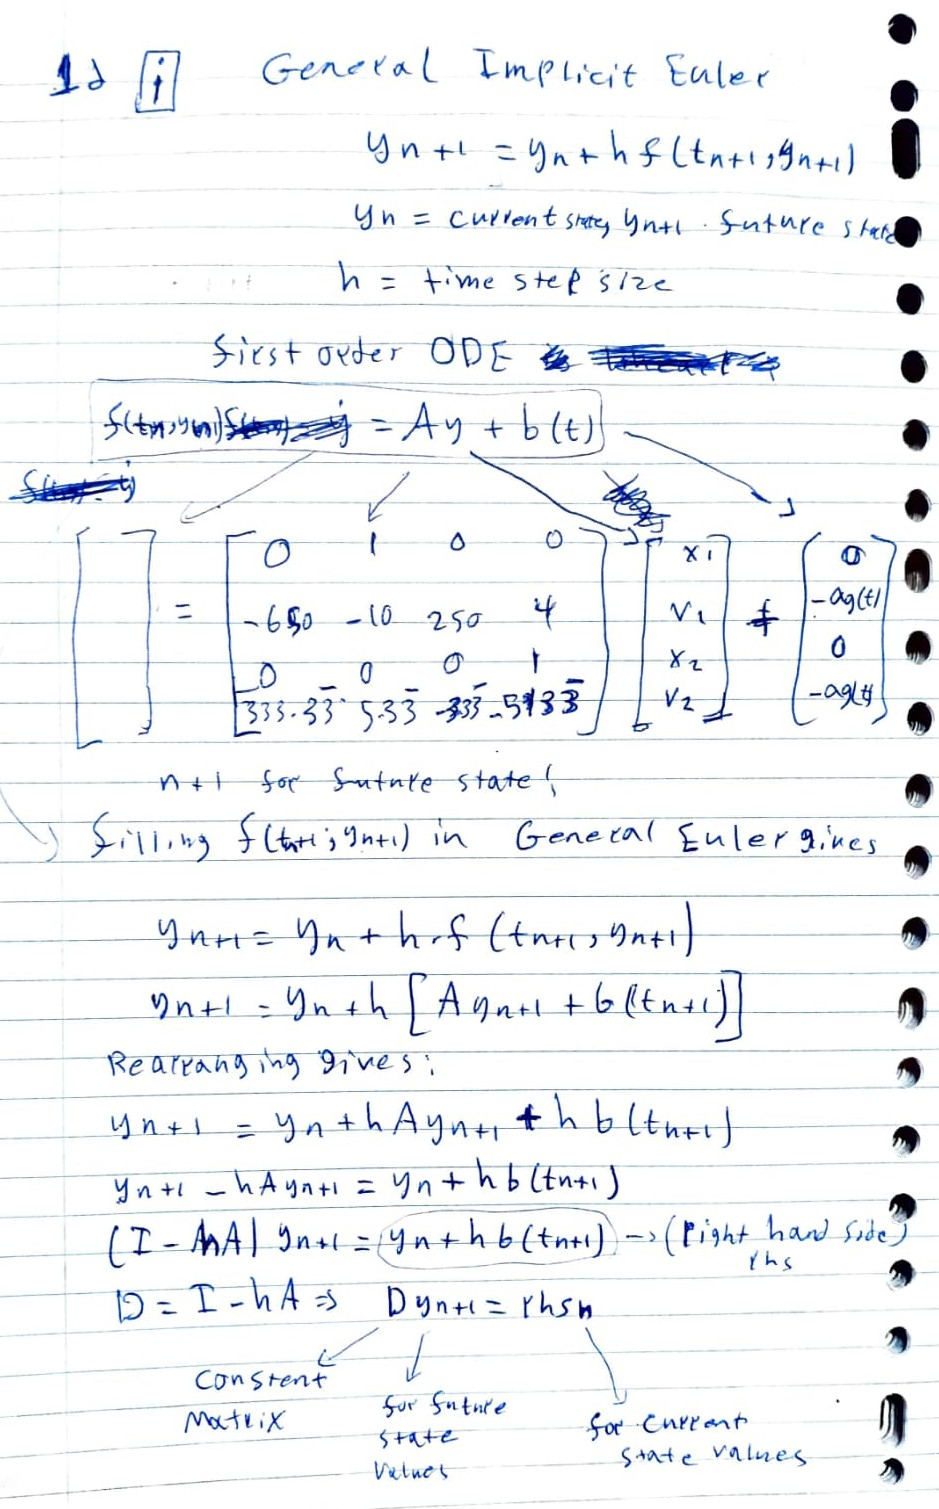

The handwritten derivation shows how the linear system for implicit euler is obtained. Since the governing equations from 1a are linear, they can be written as dy/dt = Ay + b(t), where A is the constant 4x4 matrix in the picture, built from the masses, stiffnesses and damping coefficients, and b(t) contains the ground acceleration. Implicit euler evaluates the derivative at the future time step, so y(n+1) appears on both sides of the method and cannot be computed directly like in the explicit methods. Substituting Ay + b(t) into the method and moving every term containing y(n+1) to the left hand side, as done in the picture, gives D y(n+1) = rhs(n). Here D = I - hA is a constant matrix, y(n+1) is the unknown future state, and rhs(n) is known from the current state y(n) and the ground acceleration at the new time step.

D only depends on the step size and the building parameters, so it is identical in every time step and only rhs(n) changes. Computing the inverse of D in every step would therefore be wasteful, since it costs O(n^3) each time. Instead, D is factorized once before the time stepping loop using [L, U, P] = lu(D). Each time step then only needs a forward substitution to solve for z, followed by a backward substitution to solve for y(n+1), and both cost O(n^2). The expensive factorization is paid a single time, and the for each iteration afterwards only cheap substitutions are used. 

for i = 1:length(h)

0.0065411 m


3.551 m/s^2


    [t, y] = implicit_euler(@g, initial_conditions, t0, h(i), tf);

4m/s^2



    max_delta1 = 0;
    max_delta2 = 0;
    max_a1abs = 0;
    max_a2abs = 0;

    for n = 1:length(t)

     % Floor Displacement
    delta1 = y(1, n);
    delta2 = y(3, n) - y(1, n); 
    end

figure
plot(t, y(1,:), t, y(3,:))
xlabel('Time (s)')
ylabel('Floor Displacement (m)')
legend('Floor 1', 'Floor 2')
title('Floor Displacement vs. Time')
grid on 

end

#### Solution 1d ii)

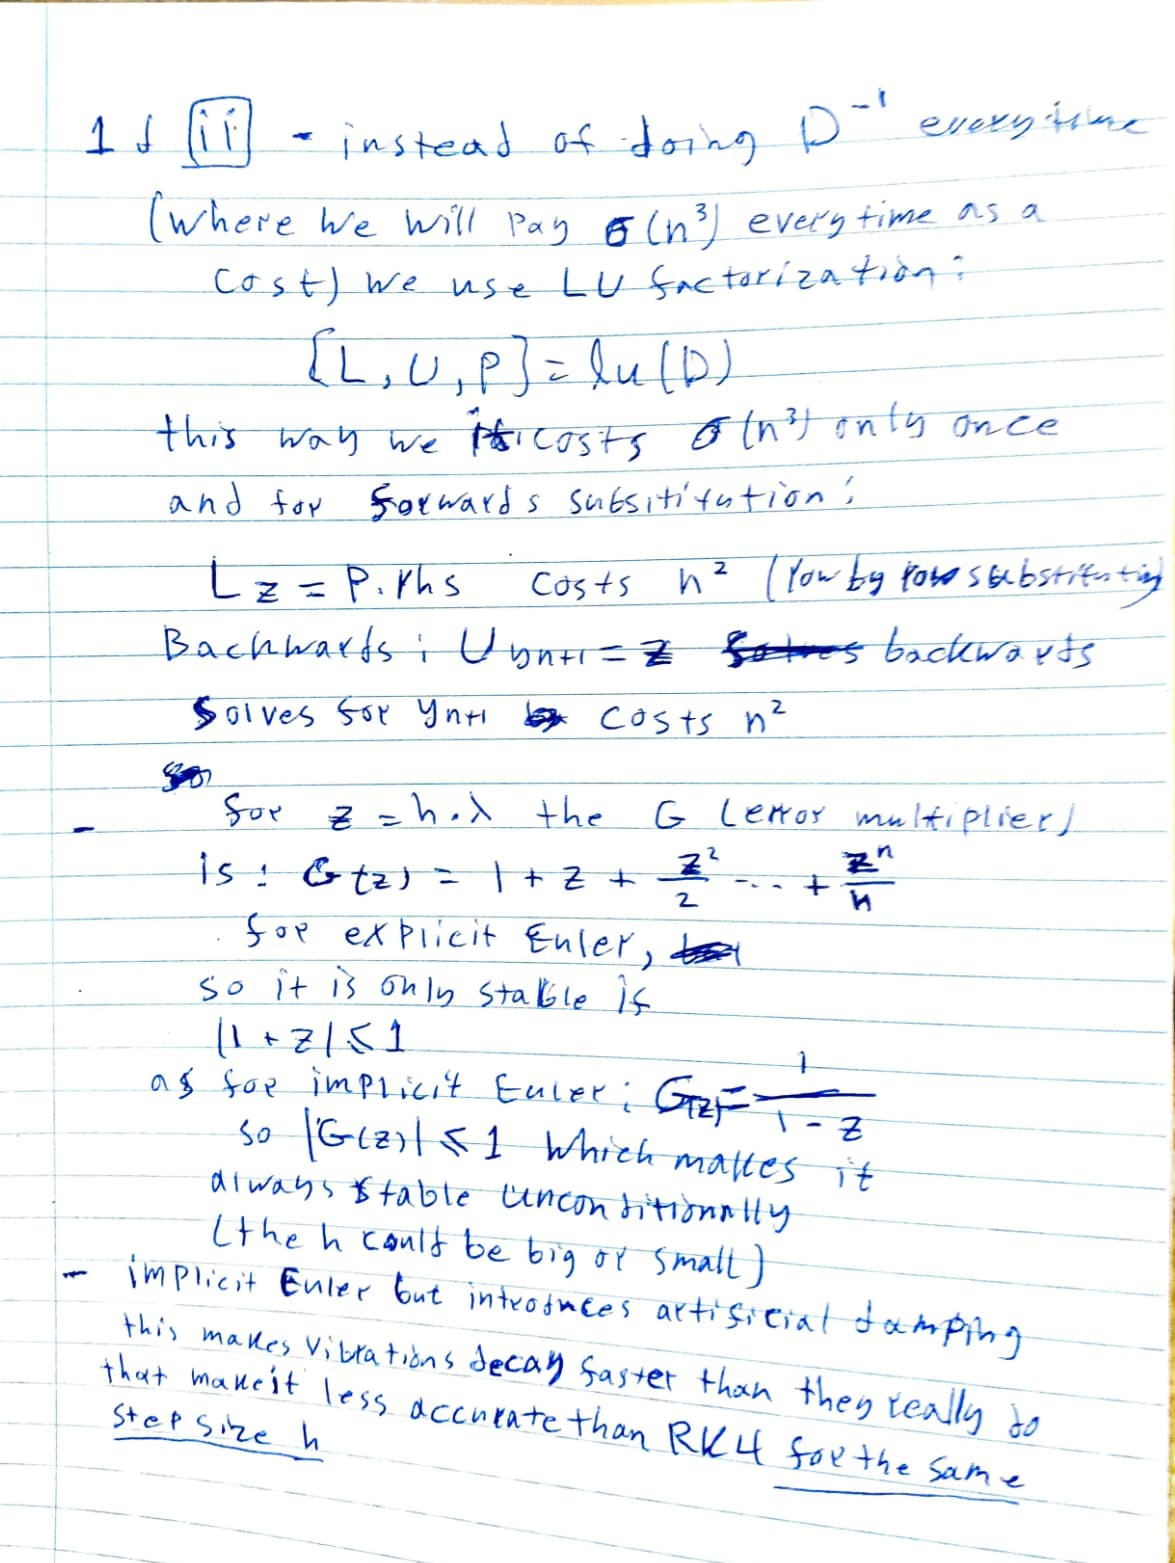

The computed solutions for the implicit euler method are stable for all of the step sizes h = 0.005, h = 0.01, h = 0.05 and h = 0.1, including the step sizes where the explicit euler and improved euler solutions diverged in 1c. The plots of implicit euler are almost identical to the reference solution in 1b, so just like in 1c the accuracy is compared through the error scaling formulas instead of visually.

The stability comes from the error multiplier G(z), where z = h*lambda and lambda is an eigenvalue of the system. Each time step multiplies the solution by G(z), so the solution only stays bounded if the magnitude of G(z) is at most one. For explicit euler, G(z) = 1 + z, which only satisfies this for a limited range of h. This is why explicit euler diverged at the larger step sizes in 1c. For implicit euler, G(z) = 1/(1 - z), and since the building is damped, all of the eigenvalues have a negative real part, which makes the magnitude of G(z) smaller than one for every h. Implicit euler is therefore unconditionally stable for this problem, so the step size does not need to be chosen to stop the solution from diverging and is only limited by how accurate the solution needs to be.

Implicit euler is a first order method, so its leading order error scales with h. The table below shows the leading order error and how many times larger it is than the reference RK4 leading order error of h^4 = 10^-16.

The table shows that the error of implicit euler is very large compared to the reference solution, ranging from $5\times {10}^{13}$ times larger at h = 0.005 to $1\times {10}^{15}$ times larger at h = 0.1. These values only compare the powers of h and ignore the constant in front of each error term, so they show how the error scales and not the exact error. Since implicit euler is a first order method, the error is directly proportional to h, so it is 20 times larger at h = 0.1 than at h = 0.005, and halving h only halves the error. For h = 0.005 and h = 0.01 the values are identical to the explicit euler values in 1c, so the only thing implicit euler gains over explicit euler is that it can be used at h = 0.05 and h = 0.1, where explicit euler diverged.

Compared to the other methods in 1c, the error of implicit euler is much larger at every step size. At h = 0.005 it is $5\times {10}^{13}$, while improved euler has $2\ldotp 5\times {10}^{11}$ and RK4 has $6\ldotp 25\times {10}^6$. The gap grows as h increases, since at h = 0.1 the error of implicit euler is $1\times {10}^{15}$, while the error of RK4 is $1\times {10}^{12}$. Even the largest RK4 step size of h = 0.1 gives a smaller error than implicit euler at its smallest step size of h = 0.005, by a factor of 50. This is because halving h reduces the error of RK4 by a factor of 16, compared to a factor of 2 for implicit euler.

A large part of this error comes from the artificial damping that implicit euler introduces, which makes the vibrations decay faster than they really do. This effect gets larger as h increases, so it should be larger for h = 0.05 and h = 0.1, even though it is not visible at the scale of the plots.

In terms of suitability, implicit euler is better than explicit euler and improved euler since it cannot diverge, and the LU factorization from 1d i) keeps the extra linear solve cheap. RK4 is still the better choice for this problem, since it was already stable for all of the tested step sizes in 1c and is far more accurate. Implicit euler would be more useful for a stiff system with very fast decaying modes, where the explicit methods would need extremely small step sizes.

### Problem 1e. Evaluate response (5 pts)

Evaluate the seismic response of the reference building. Consider the floor displacements, interstory drifts, and absolute floor accelerations, and determine whether the building satisfies all the structural performance requirements. Discuss the relationship between structural stiffness, damping, interstory drift, floor acceleration, structural safety, and occupant comfort.

# Solution 1e

Utilizing the reference solution from 1b which utilizes RK4 with a step size of h = 0.0001, the displacement and absolute acceleration of both floors has already been simulated and recorded. Now, what is left is to analyze the obtained values and determine whether the building satisfies the structural performance requirements.

disp([ num2str(max(floor_displacement(1, :))) , ' m'])
disp([ num2str(max(floor_displacement(2, :))) , ' m'])
disp([ num2str(max(floor_acceleration(1, :))) , ' m/s^2'])
disp([ num2str(max(floor_acceleration(2, :))) , 'm/s^2'])

Both the maximum displacement of the first floor and the maximum displacement of the second floor fall within the allowable thresholds set out by the structural performance requirements. For this specific earthquake and reference building, both floors stay sufficiently close to their starting locations and the maximum displacement thresholds for both floors are satisfied. Due to the equations which govern delta1 and delta 2, as well as the plotted reference displacement-time graph in 1 b), we can see that the value which delta 2 is measuring is the interstory drift itself, which is, just how much further is the second floor being displaced compared to the first floor.

This indicates that the stiffness of the building is sufficiently high, keeping the overall displacement below the critical thresholds. 

On the other hand, the absolute acceleration of the second floor (and in fact, the first floor as well) exceeds the limit of 4 m/s^2 set out by the structural performance requirements and reaches a maximum value of approximately 5.35 m/s^2 (and 4.3 m/s^2 for the first floor). This means that this third requirement is not satisfied and that the reference building does not properly account for the structural performance requirements since it is not constructed with the maximum acceleration criterion in mind.

The breach of the floor acceleration threshold negatively affects occupant comfort as the building rapidly accelerates the occupants in alternating directions in the event of an earthquake in addition to potentially damaging equipment within the building. In order to reduce the absolute floor acceleration of the building, the building would either require a higher stiffness or increased damping. A good solution to the excessive absolute floor acceleration would be the inclusion of stronger dampers which would more actively dissipate the kinetic energy of the floors while they are in motion, thereby reducing the absolute floor acceleration experienced during an earthquake; however, increasing the stiffness would also lead to a reduction to both the displacement and the absolute floor acceleration.

### Problem 1f. Challenging extension: building modifications (10 pts)

We will investigate the possibility of modifying the story stiffnesses to ensure the building meets all structural performance requirements. Consider multiplying both story stiffnesses by a common factor $$\alpha\geq1$$, so that $$k_1^{\mathrm{new}}=\alpha k_1$ and $k_2^{\mathrm{new}}=\alpha k_2$$. The goal of this exercise is to compute the smallest value of $\alpha$ that reaches the performance boundary. Use a root-finding method to find the smallest such $\alpha$. You may not use a built-in root-finding method, you must use your implementation of one of the algorithms discussed during the course. On each iteration of the root-finding algorithm, you will compute a new numerical simulation to the building response.

After you computed $\alpha$, repeat the simulation with the new story stiffnesses and verify that every performance requirement is satisfied.

# Solution 1f

To find the smallest stiffness scaling factor that satisfies the performance requirements, the governing equations from 1a have to be solved for different values of alpha. The function g alpha is identical to g from 1a, except that the stiffnesses k1 and k2 are multiplied by alpha, so g alpha with alpha = 1 gives back the reference building. 

% Governing equations with both story stiffnesses scaled by alpha
function dy = g_alpha(t, y, alpha)
    m1 = 20000;
    m2 = 15000;
    k1 = alpha * 8000000;
    k2 = alpha * 5000000;
    c1 = 120000;
    c2 = 80000;

    dy = [y(2);
          -ag(t) - (c1*y(2) + c2*y(2) - c2*y(4) + k1*y(1) + k2*y(1) - k2*y(3))/m1;
          y(4);
          -ag(t) - (c2*y(4) - c2*y(2) + k2*y(3) - k2*y(1))/m2];
end

The three performance requirements are combined into a single function perf(alpha). Each response quantity is divided by its limit, and the largest of the three ratios minus one is returned. If perf is larger than zero, at least one requirement is violated, and if perf is smaller than zero, all of the requirements are met. The boundary of the performance requirements is therefore the root of perf, and the smallest alpha that reaches the boundary is the approximate root. Each evaluation of perf runs a new RK4 simulation of the building with the modified stiffnesses, and the maximum drifts and the maximum absolute acceleration of the second floor are taken from that simulation.

% Performance function perf(alpha) = max(ratios) - 1
% perf > 0: at least one requirement is violated, F < 0: all requirements are met
function perf = performance_function(alpha, h, t0, tf, x0)
    m2 = 15000;
    k2 = alpha * 5000000;
    c2 = 80000;

    [~, y] = RK4(@(t, y) g_alpha(t, y, alpha), x0, t0, h, tf);

    % Maximum interstory drifts
    ratio1 = max(abs(y(1, :))) / 0.030;            % first-story drift limit [m]
    ratio2 = max(abs(y(3, :) - y(1, :))) / 0.025;  % second-story drift limit [m]

    % Absolute acceleration of floor 2: a2 + ag = -(c2*(v2-v1) + k2*(x2-x1))/m2
    a2abs = -(c2*(y(4, :) - y(2, :)) + k2*(y(3, :) - y(1, :)))/m2;
    ratio3 = max(abs(a2abs)) / 4.0;                % acceleration limit [m/s^2]

    perf = max([ratio1, ratio2, ratio3]) - 1;
end

The bisection method was chosen as the root-finding method. It requires and upper bound guess and a lower bound guess where the lower bound is unsuitable and yields a positive value and the upper bound is suitable and yields a negative value. 

From 1e, the reference building alpha = 1 exceeds the acceleration limit, so perf(1) is larger than zero. The upper bracket was set to alpha = 2, where perf(2) yields a value smaller than 0 and indicates that all conditions are satisfied. This means that a root exists between the two alphas in question.

The system was evaluated with a step size of h = 0.0001 utilizing the RK4 method, since every iteration of the root finding method requires a full simulation and this was the chosen step size and method for the reference solution.

% Bisection method configuration
h_root  = 0.0001;    % time step used inside the root search
alpha_l = 1.0;      % lower bracket: reference building (perf > 0)
alpha_u = 2.0;      % upper bracket (perf < 0 is required for the bracket to be valid)
maxit   = 100;
tol     = 1e-6;

% Each evaluation of perf runs a new RK4 simulation of the building
perf = @(alpha) performance_function(alpha, h_root, t0, tf, initial_conditions);


[alpha_design, alpha_vec] = bisection_method(perf, alpha_l, alpha_u, maxit, tol);

After simulating the building utilizing RK4 with various alphas and determining the approximate alpha at which the root is located (alpha_design), the reference simulation was conducted again with the modified alpha value in order to confirm that all three conditions are satisfied with the modified stiffness of the building.

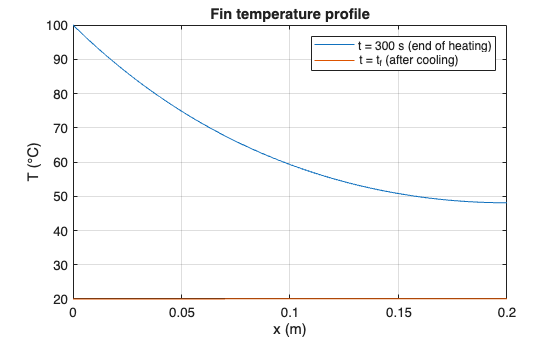

% Verification of Building Behaviour with modified alpha
h  = 0.0001;
t0 = 0;
tf = 15;


g_modified = @(t, y) g_alpha(t, y, alpha_design);

[t, y] = RK4(g_modified, initial_conditions, t0, h, tf);

max_delta1 = 0;
max_delta2 = 0;
max_a1abs = 0;
max_a2abs = 0;

floor_displacement = zeros(2, length(t));
floor_acceleration = zeros(2, length(t));

for n = 1:length(t)


dt_lim = 0.1480

 % Floor Displacement
 delta1 = y(1, n);
 delta2 = y(3, n) - y(1, n);

 % Absolute Floor Acceleration
 dy = g_modified(t(n), y(:, n));
 a1abs = dy(2) + ag(t(n));
 a2abs = dy(4) + ag(t(n));

 
 % List of Floor Displacement's and Floor Acceleration
 floor_displacement(1, n) = delta1;
 floor_displacement(2, n) = delta2;
 floor_acceleration(1, n) = a1abs;
 floor_acceleration(2, n) = a2abs;

end

alpha_design
disp([ num2str(max(floor_displacement(1, :))) , ' m'])
disp([ num2str(max(floor_displacement(2, :))) , ' m'])

dt = 0.050 s (0.34 x limit): max|T| = 97
dt = 0.100 s (0.68 x limit): max|T| = 97
dt = 0.120 s (0.81 x limit): max|T| = 97
dt = 0.125 s (0.84 x limit): max|T| = 97
dt = 0.150 s (1.01 x limit): max|T| = 2.12e+62
dt = 0.200 s (1.35 x limit): max|T| = Inf
dt = 0.250 s (1.69 x limit): max|T| = Inf
dt = 0.500 s (3.38 x limit): max|T| = Inf


disp([ num2str(max(floor_acceleration(1, :))) , ' m/s^2'])
disp([ num2str(max(floor_acceleration(2, :))) , 'm/s^2'])

The bisection method converged to alpha = 1.7487, which means that the stiffnesses of the building need to be increased by about 75% compared to the reference building.

The verification simulation gives a maximum first-story drift of 0.0089305 m, a maximum second-story drift of 0.0065411 m, and a maximum absolute acceleration of the second floor of 4 m/s^2.

With regards to the structural performance criteria, both of the drift requirements are satisfied, while the absolute acceleration of the second floor is exactly at the limit indicating that a safer choice for alpha which ensures that the absolute floor acceleration of the second floor is less than the limit with a sufficient margin would be at approximately alpha = 1.75.

Utilizing the bisection method, the smallest possible alpha has been determined which satisfies the structural performance requirements of the building under the simulated conditions.

## Problem 2: Transient Heat Transfer in a Cooling Fin (28 pts)

Cooling fins are commonly used to increase the transfer of heat between a hot surface and the surrounding environment. They are found in electronic cooling systems, engines, heat exchangers, and many other thermal systems.

Consider a straight rectangular fin attached to the surface of an electronic device. When the device is turned on, the temperature at the base of the fin increases. Heat is conducted along the fin and transferred from its surface to the surrounding air by convection.

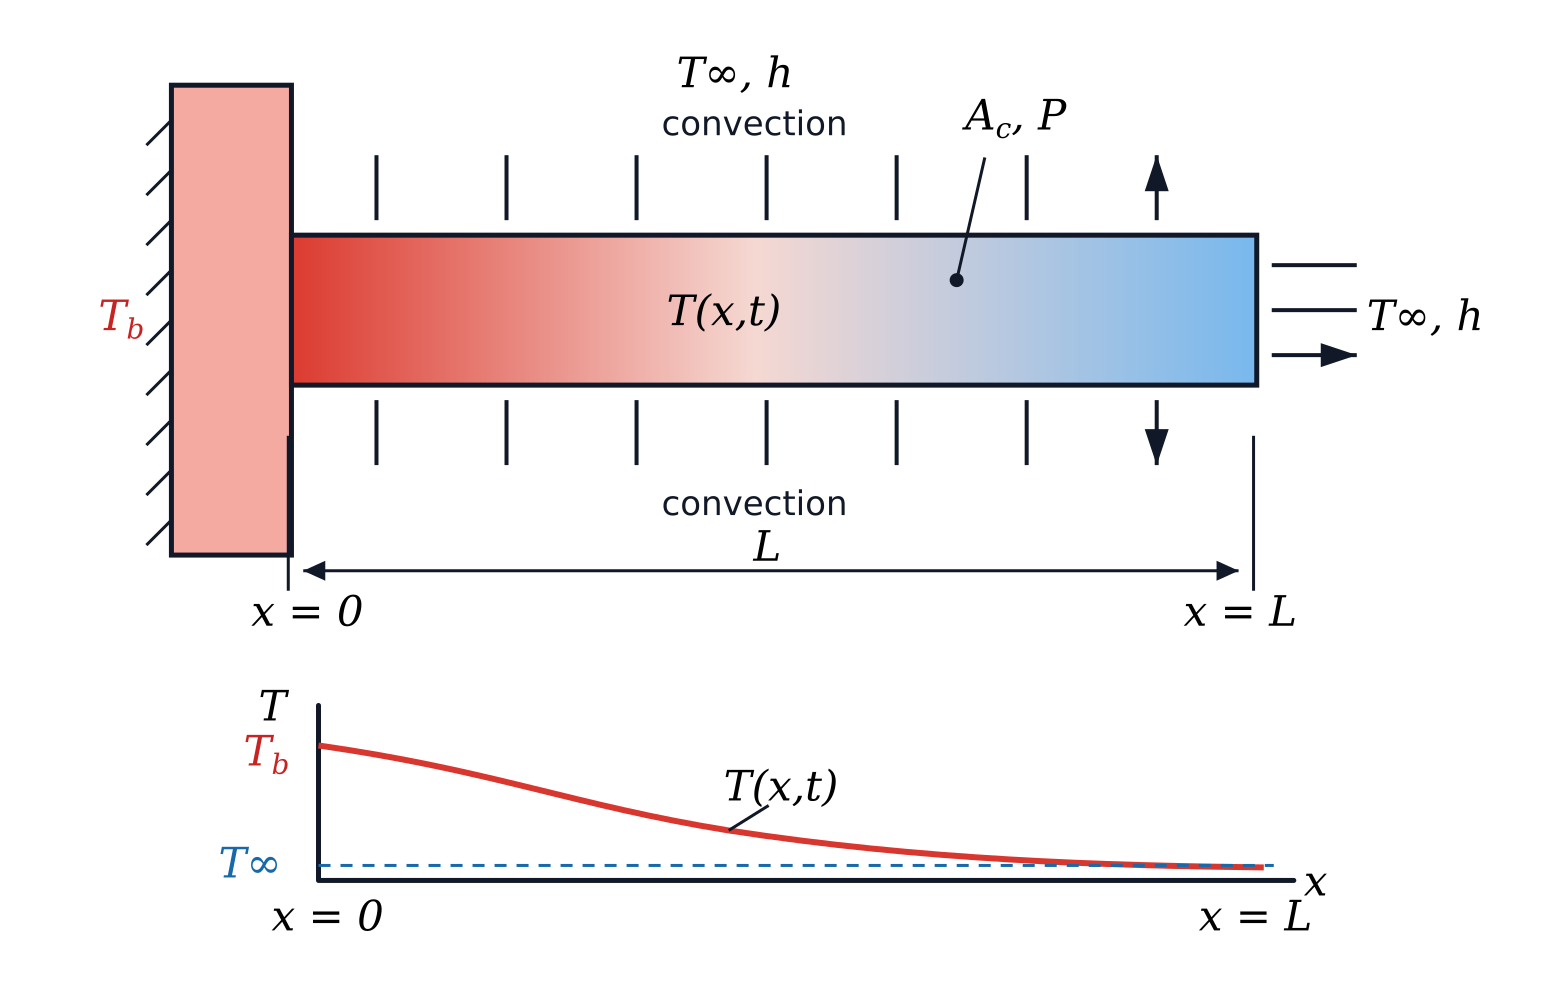

The temperature distribution in the fin is denoted by $T(x,t)$, where $x$ is the distance measured from the base of the fin and $t$ is time.

Assuming one-dimensional heat conduction, constant material properties, and uniform convection over the fin surface, the temperature is governed by


$$
 \rho c_p A_c
 \frac{\partial T}{\partial t}
 =
 kA_c\frac{\partial^2T}{\partial x^2}
 -hP\left(T-T_\infty\right)$$


for


$$
 0<x<L,
 \qquad
 0<t\leq t_{\mathrm{end}}$$


Equivalently,


$$
 \frac{\partial T}{\partial t}
 =
 \alpha\frac{\partial^2T}{\partial x^2}
 -\beta\left(T-T_\infty\right)$$


where


$$
 \alpha=\frac{k}{\rho c_p}
$$


is the thermal diffusivity and


$$
 \beta=\frac{hP}{\rho c_pA_c}
$$


represents the effect of convection from the lateral surface.

The parameters appearing in the model are:

- $k$: thermal conductivity

- $\rho$: material density

- $c_p$: specific heat capacity

- $h$: convective heat-transfer coefficient

- $A_c$: cross-sectional area of the fin

- $P$: exposed perimeter of the fin

- $T_\infty$: ambient temperature

- $L$: fin length

### Fin geometry and material properties

The reference fin is made of aluminum and has a rectangular cross-section.

Use the following parameters:

For a rectangular cross-section, the cross-sectional area is


$$
 A_c=wb$$


and the exposed perimeter is


$$
 P=2(w+b)$$


### Initial and boundary conditions

Initially, the fin is at the same temperature as the surrounding air:


$$
 T(x,0)=T_\infty=20^\circ\mathrm{C},
 \qquad
 0\leq x\leq L$$


The electronic device operates for 300 seconds. During this period, the base of the fin is maintained at


$$
 T_b=100^\circ\mathrm{C}$$


After 300 seconds, the device is switched off and the base temperature returns to the ambient temperature.

The base boundary condition is therefore


$$
 T(0,t)=T_b(t)$$


where


$$
 T_b(t)=
 \begin{cases}
 100^\circ\mathrm{C},
 &0<t\leq300\ \mathrm{s}\\[4pt]
 20^\circ\mathrm{C},
 &t>300\ \mathrm{s}
 \end{cases}
$$


Assume that heat transfer from the tip of the fin is negligible. Therefore, the tip is modeled as insulated:


$$
 \frac{\partial T}{\partial x}(L)
 =0$$


Simulate the temperature distribution over


$$
 0\leq t\leq900\ \mathrm{s}$$


This interval includes:

1. the transient heating of the fin

2. the approach toward a steady temperature distribution

3. the cooling process after the device is switched off

### Spatial discretization

Divide the spatial domain into $N$ intervals of equal length, such that the $N+1$ nodes are


$$
 x_i=i\Delta x,
 \qquad
 i=0,1,\ldots,N,
$$


where


$$
 \Delta x=\frac{L}{N}$$


The temperature at node $x_i$ and time $t_n$ is approximated by


$$
 T_i^n\approx T(x_i,t_n)$$


Use a second-order central difference approximation for the spatial derivative and explicit Euler for the time derivative.

### Problem 2a. Derive finite-difference approximation (4 pts)

Discretize the spatial domain using central finite differences and incorporate the initial and boundary conditions. Explain how the insulated-tip condition is applied at $$x=L$$. You may use a picture of a hand-written derivation.

# Solution 2a (no code)

Our PDE is


$$\frac{\partial T}{\partial t} = \alpha \frac{\partial^2 T}{\partial x^2} - \beta\,(T - T_\infty)$$


where alpha is,


$$
 \alpha=\frac{k}{\rho c_p}
$$


and beta is,


$$
 \beta=\frac{hP}{\rho c_pA_c}
$$


First our fin is split into intervals of size delta x

     
$$\Delta x = \frac{L}{N},$$


Seperating these intervals are nodes going from 0 to N, therefore we have N +1 nodes. Here $x_0$ is the base and $x_N$ is the tip of the fin.


$$\quad i = 0,1,\dots,N$$


 So our intervals are,


$$\qquad x_i = i\,\Delta x$$


So


$$ \qquad T_i(t) \approx T(x_i,t)$$


No we can do the Taylor expansion of T around $x_i$. Since we add the + and the - the odd terms cancel out


$$T_{i+1} + T_{i-1} = 2T_i + \Delta x^2\,T'' + \frac{\Delta x^4}{12}\,T'''' + \cdots$$



$$\frac{\partial^2 T}{\partial x^2}\bigg|_{x_i} = \frac{T_{i+1} - 2T_i + T_{i-1}}{\Delta x^2} $$


We can substitue this into our PDE so that we get an ODE equation per node


$$\frac{dT_i}{dt} = \alpha\,\frac{T_{i+1} - 2T_i + T_{i-1}}{\Delta x^{2}} - \beta\,\bigl(T_i - T_\infty\bigr)$$


The fin starts at a base temperature


$$T_i(0) = T_\infty, \qquad i = 0, 1, \dots, N$$


The base temperature the following funciton of time


$$
T_0(t) = T_b(t) =
\begin{cases}
T_{\text{on}}, & 0 \le t \le 300\ \text{s} \\
T_\infty, & t > 300\ \text{s}
\end{cases}
$$


The tip of the fin (L) is insulated therfore


$$\frac{\partial T}{\partial x}\bigg|_{x = L} = 0$$


Since the node at N is at the end of the fin it has no right hand neighneighbour, we can introduce what is called a ghost node. While this node does not actually exist it allows us to apply a central difference theorem at $x_N$. 


$$\frac{T_{N+1} - T_{N-1}}{2\,\Delta x} = 0
\quad \Longrightarrow \quad
T_{N+1} = T_{N-1}$$


Since $T_{N+1}$ is equal to $T_{N-1}$ we know tthat no head flows through the tip.

We can substitute this into our equation.


$$\frac{dT_N}{dt} = \alpha\,\frac{2\,(T_{N-1} - T_N)}{\Delta x^{2}} - \beta\,\bigl(T_N - T_\infty\bigr)$$


Back to all other nodes.

To discretise time we can use the Explicit Euler method where we divide time into steps $t_n$ $=$ $n \Delta$t . The time derivative of $t_n$ is approximated with a forward difference.  


$$\frac{\partial T}{\partial t}\bigg|_{x_i,t_n} \approx \frac{T_i^{n+1} - T_i^n}{\Delta t}$$


Plugging this into our equation 


$$\frac{T_i^{n+1} - T_i^n}{\Delta t} = \alpha\,\frac{T_{i+1}^n - 2T_i^n + T_{i-1}^n}{\Delta x^2} - \beta\,(T_i^n - T_\infty)$$


Rearragning  our equation becomes,


$$T_i^{n+1} = T_i^n + \Delta t\left[\alpha\,\frac{T_{i+1}^n - 2T_i^n + T_{i-1}^n}{\Delta x^2} - \beta\,(T_i^n - T_\infty)\right]$$


For the tip our equation is,


$$T_N^{n+1} = T_N^n + \Delta t\left[\frac{2\alpha\,(T_{N-1}^n - T_N^n)}{\Delta x^2} - \beta\,(T_N^n - T_\infty)\right]$$


### Problem 2b. Numerically simulate a solution (5 pts)

Compute a numerical solution to the transient heat-transfer problem. Use a suitable spatial step-size and a time-step size and simulate the complete heating and cooling cycle. Do not use built-in partial differential equation solvers.

# Solution 2b

#### Parameters

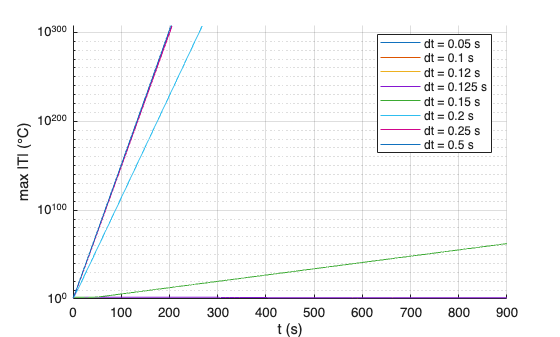

L = 0.2; %Fin length (m)

w = 0.04; %Fin width (m)
b = 0.004; %Fin thickness (m)
k = 205; %Thermal conductivity (W/mK)
rho = 2700; %Density (kg/m^3)
c_p = 900; %Specific heat capacity (J/kgK)
chc = 25; %Convective heat-transfer coefficient (W/m^2K), h in assignment pdf
T_inf = 20; %Ambient temperature (C)

P = 2*(w+b); %Exposed perimeter of the fin (m)
A_c = w*b; %Cross-sectional area of the fin (m^2)

alpha = k/(rho*c_p); 
beta = chc*P/(rho*c_p*A_c);

T_on = 100;
t_off = 300;
T_b = @(t) T_on*(t <= 300 + 1e-9) + T_inf*(t > t_off + 1e-9); %Time function

 A function for the base temperature in terms of time. 1e-9 is added to prevent rounding errors since 300 isn't stores as exactly 300.

Our fin is cut into 100 segmetns where each segment is dx distance apart. Our time step size 0.02 seconds and our simulation time is 900 seconds.

N  = 100; %Number of intervals 
dx = L/N; %Node spacing
dt = 0.02; %Time step size
tf = 900; %Simulation time
t0 = 0; %Initial time
tf = 900; %Final time

Here we create our matrices


e = ones(N,1); %Matrix Nx1 filled with ones
M = (alpha/dx^2) * spdiags([e -2*e e], -1:1, N, N); %Builds a tridiagonal matrix so that row i computes the conduction term
M(N, N-1) = 2*alpha/dx^2;  % Our insulated tip/ghost node
M = M - beta*speye(N); %Add convection term to every entry


Our right hand side equations. Bvec does not depend on u. f is the complete right hand side in terms of t and u that is going to be solved.

bvec = @(t) [alpha/dx^2*T_b(t); zeros(N-1,1)] + beta*T_inf*ones(N,1);
f = @(t, u) M*u + bvec(t);

Our initial conditions at $T_{inf}$ and calling our function.

u0 = T_inf*ones(N,1);

[t, u] = explicit_euler(f, u0, t0, dt, tf);

Adding the base temperature

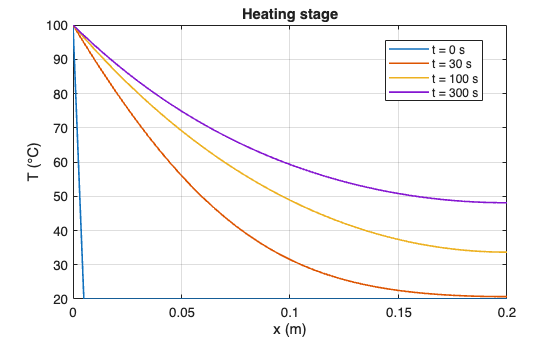

Thist = [T_b(t); u];    
x = linspace(0, L, N+1);

figure
plot(x, Thist(:, round(300/dt)+1), x, Thist(:, end))
xlabel('x (m)'); ylabel('T (°C)')
legend('t = 300 s (end of heating)', 't = t_f (after cooling)')

title('Fin temperature profile')
grid on

### Problem 2c. Investigate stability region (5 pts)

Select $  $$
  \Delta x=0.005\ \mathrm{m}
  $$$ and investigate how the computed solution is affected by the time step-size. For this problem, an approximate stability requirement for explicit Euler is


$$  $$
  \Delta t
  \leq
  \frac{1}
  {
  \frac{2\alpha}{\Delta x^2}+\beta
  }
  $$
$$


Compare the theoretical stability restriction with the behavior observed in the numerical simulations.

# Solution 2c

Our new dx of 0.005m and n of 40.

dx = 0.005;
N = 40;

From the equation above we can find our theoretical limit for the time step size.

dt_lim  = 1/(2*alpha/dx^2 + beta)

Our time steps to check the stability of

dt_list = [0.05 0.1 0.12 0.125 0.15 0.2 0.25 0.5];

We can rebuild everything with our N

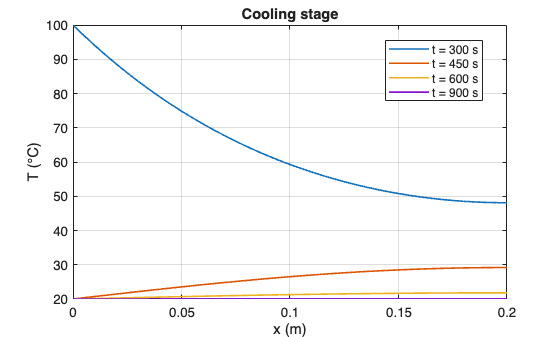

e = ones(N,1);                         
M = (alpha/dx^2) * spdiags([e -2*e e], -1:1, N, N);
M(N, N-1) = 2*alpha/dx^2;

M = M - beta*speye(N);
bvec = @(t) [alpha/dx^2*T_b(t); zeros(N-1,1)] + beta*T_inf*ones(N,1);
f    = @(t, u) M*u + bvec(t);
u0   = T_inf*ones(N,1);

figure; hold on
for i = 1:length(dt_list)
    [t, u] = explicit_euler(f, u0, t0, dt_list(i), tf);
    Tmax = max(abs(u), [], 1);
    plot(t, Tmax)

Fin is below 30 °C at t = 442.2 s, i.e. 142.2 s after switch-off


    fprintf('dt = %.3f s (%.2f x limit): max|T| = %.3g\n', ...
            dt_list(i), dt_list(i)/dt_lim, max(Tmax));
end
set(gca, 'YScale', 'log'); grid on
xlabel('t (s)'); ylabel('max |T| (°C)')
legend(compose('dt = %g s', dt_list), 'Location', 'best')

As we can see from both the plot and the list above when the time step exceeds the theoretical stability limit of 0.1480 out max T blows up. A time step of 0.150 is already 2.12e+62 and anything large goes to infinity.

### Problem 2d. Investigate heating and cooling (6 pts)

i. Use


$$  $$
  \Delta x=0.005\ \mathrm{m}
  $$$$


and an appropriate time-step size. Plot the temperature distribution at


$$  $$
  t=0,\ 30,\ 100,\ 300,\ 450,\ 600,\ 900\ \mathrm{s}
  $$$$


The selected times should clearly demonstrate the heating stage, the moment at which the device is switched off, and the subsequent cooling stage. Plot the solutions in the heating stage in one plot and the solutions in the cooling stage in one plot.

ii. After the electronic device is switched off at $$t=300\ \mathrm{s}$$, determine the time required for the entire fin to cool below


$$  $$
  30^\circ\mathrm{C}
  $$$$


Define the cooling time as the first time after $$t=300\ \mathrm{s}$$ for which

$  $$
  \max_{0\leq x\leq L}T(x,t)
  <
  30^\circ\mathrm{C} $$$.

# Solution 2d

Setting our segment number, segment size, time step size and final time. Time step size was chosen as 0.1 because we know from earlier that that is stable. Final time was chosen as 1000 because it should be long enough for the fin to cool.

dx = 0.005;  
N = 40;      
dt = 0.1; 
tf = 1000;


Rebuilidng and rerunning everything with our conditions

e = ones(N,1);
M = (alpha/dx^2) * spdiags([e -2*e e], -1:1, N, N);

Energy transferred = 8084.7 J


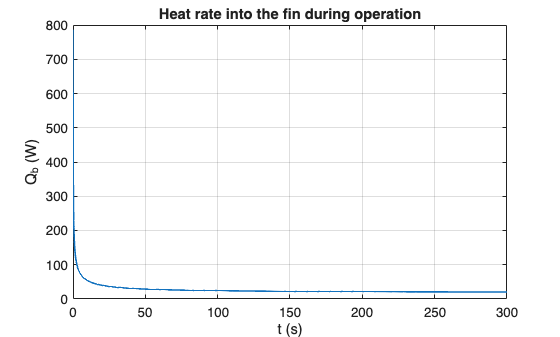

M(N, N-1) = 2*alpha/dx^2;
M = M - beta*speye(N);

bvec = @(t) [alpha/dx^2*T_b(t); zeros(N-1,1)] + beta*T_inf*ones(N,1);
f = @(t, u) M*u + bvec(t);
u0 = T_inf*ones(N,1);


[t, u] = explicit_euler(f, u0, t0, dt, tf);
Thist = [T_b(t); u];
x = linspace(0, L, N+1);

Plotting the heating stage

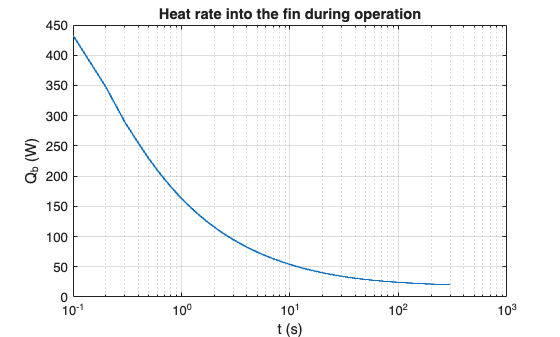

t_heat = [0 30 100 300];         
idx = round(t_heat/dt) + 1;
figure
plot(x, Thist(:, idx), 'LineWidth', 1.2)
xlabel('x (m)'); ylabel('T (°C)'); grid on

legend(compose('t = %g s', t_heat), 'Location', 'best')
title('Heating stage')

From the plot we can observe that at a small time the drop in temperature as we move along the fin is steep. As the heating time increases the drop in temperature becomes more gradual. This makes sense since the fin is being heated, from ambient temperature, at the base. Therefore at low values of t the end of the fin is still cool while the base will have already heated up. The curves are all flat at 0.2 since the tip of the fin is insulated meaning no heat is lost to convection with the air.

Plotting the cooling time

t_cool = [300 450 600 900];    
idx = round(t_cool/dt) + 1;
figure
plot(x, Thist(:, idx), 'LineWidth', 1.2)
xlabel('x (m)'); ylabel('T (°C)'); grid on
legend(compose('t = %g s', t_cool), 'Location', 'best')
title('Cooling stage')

We can observe that during the cooling stages the base of the fin cools down rapidly. At 450 seconds the entire fin has cooled to below 30 degrees. All the lines are flat at 0.2 because the tip is insulated meaning no heat is lost to convection with the air.

Finding our the time taken for all of the fin to cool to below 30 degrees.

T_thr = 30;                                
Tmax  = max(Thist, [], 1);                  
j = find(t > 300 & Tmax < T_thr, 1);        
t_cool_time = t(j) - 300;
fprintf('Fin is below %g °C at t = %.1f s, i.e. %.1f s after switch-off\n', ...
        T_thr, t(j), t_cool_time)

### Problem 2e. Challenging extension: e**valuate the thermal performance (8 pts)**

i. Calculate the heat-transfer rate from the base into the fin using


$$  $$
  \dot{Q}_b(t)
  =
  -kA_c
  \left.
  \frac{\partial T}{\partial x}
  \right|_{x=0}
  $$$$


Approximate the temperature gradient at the base using an appropriate finite-difference formula.

ii. Calculate the total thermal energy transferred to the fin during the operation of the device:


$$  $$
  E_{\mathrm{transferred}}
  =
  \int_0^{300}
  \dot{Q}_b(t)\,dt
  $$$$


Approximate the time integral using a suitable numerical integration method.

# Solution 2e

The heat flow into the fin at the base. No nodes on the left, because at base, so we can not use central difference. One sided (forward) difference is used instead.

dTdx = (-3*Thist(1,:) + 4*Thist(2,:) - Thist(3,:)) / (2*dx);   
Q_b   = -k*A_c*dTdx;

Energy transfered into fin. The integral is calculated using the trapezoidal rule since it's accurate for second order and it's computationally cheap.

n300 = round(300/dt) + 1;                 
E = trapz(t(1:n300), Q_b(1:n300));         
fprintf('Energy transferred = %.1f J\n', E)

Plotting

figure
plot(t(1:n300), Q_b(1:n300), 'LineWidth', 1.2)
xlabel('t (s)'); ylabel('Q_b (W)'); 
grid on
title('Heat rate into the fin during operation')

We observe a high peak which then plateaus at about 20W. 

Plotting in log

figure
semilogx(t(2:n300), Qb(2:n300), 'LineWidth', 1.2)
xlabel('t (s)'); ylabel('Q_b (W)'); 
grid on
title('Heat rate into the fin during operation')